
cc
cd('D:\COOXUPE\AMOSTRAS - IMPUREZAS\Detalhadas')
load('vetor_nir_vis.mat', 'pred_nir', 'pred_vis', 'real_nir', 'real_vis')

catacao = [
    pred_nir(:,14), ... % ardido
    pred_nir(:,15), ... % brocado
    pred_nir(:,16), ... % cabeça
    pred_nir(:,20), ... % concha
    pred_nir(:,24), ... % preto
    pred_nir(:,25), ... % quebrado
    pred_nir(:,27), ... % verde
    ];
impureza = [
    pred_nir(:,22), ... % pau
    pred_nir(:,19), ... % coco
    pred_nir(:,18), ... % casca
    pred_nir(:,21), ... % pergaminho
    pred_nir(:,23), ... % pedra
    pred_nir(:,26), ... % torrão
    ];

pred_impureza_grao_nir = sum(cell2mat(impureza), 2);
pred_catacao_grao_nir = sum(cell2mat(catacao), 2);
clear impureza catacao
catacao = [
    pred_vis(:,14), ... % ardido
    pred_vis(:,15), ... % brocado
    pred_vis(:,16), ... % cabeça
    pred_vis(:,20), ... % concha
    pred_vis(:,24), ... % preto
    pred_vis(:,25), ... % quebrado
    pred_vis(:,27), ... % verde
    ];
impureza = [
    pred_vis(:,22), ... % pau
    pred_vis(:,19), ... % coco
    pred_vis(:,18), ... % casca
    pred_vis(:,21), ... % pergaminho
    pred_vis(:,23), ... % pedra
    pred_vis(:,26), ... % torrão
    ];
pred_impureza_grao_vis = sum(cell2mat(impureza), 2);
pred_catacao_grao_vis = sum(cell2mat(catacao), 2);


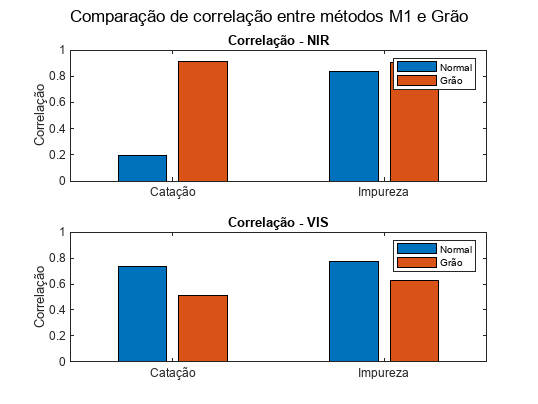


load('dados_p_boosting.mat', 'pred_area_nir', 'pred_area_vis')
[~, idx_out] = retirarnanvazio(pred_area_vis(:,1));
pred_area_vis(idx_out, :) = [];
real_vis(idx_out, :) = [];
pred_vis(idx_out, :) = [];
pred_impureza_grao_vis(idx_out, :) = [];
pred_catacao_grao_vis(idx_out, :) = [];
real_nir_catacao = cell2mat(real_nir(:,1));
real_nir_impureza = cell2mat(real_nir(:,2));

real_vis_catacao = cell2mat(real_vis(:,1));
real_vis_impureza = cell2mat(real_vis(:,2));
%lembrar de retirar os NaN e []
pred_catacao_nir = cell2mat(pred_area_nir(:,1));
pred_catacao_vis = cell2mat(pred_area_vis(:,1));
pred_impureza_nir = cell2mat(pred_area_nir(:,2));
pred_impureza_vis = cell2mat(pred_area_vis(:,2));



Cgrao_catacao_nir = corrcoef(real_nir_catacao(:,1),pred_catacao_grao_nir(:,1));
Cgrao_impureza_nir = corrcoef(real_nir_impureza(:,1),pred_impureza_grao_nir(:,1));
Cgrao_catacao_vis = corrcoef(real_vis_catacao(:,1),pred_catacao_grao_vis(:,1));
Cgrao_impureza_vis = corrcoef(real_vis_impureza(:,1),pred_impureza_grao_vis(:,1));

C_catacao_nir = corrcoef(real_nir_catacao(:,1),pred_catacao_nir(:,1));
C_impureza_nir = corrcoef(real_nir_impureza(:,1),pred_impureza_nir(:,1));
C_catacao_vis = corrcoef(real_vis_catacao(:,1),pred_catacao_vis(:,1));
C_impureza_vis = corrcoef(real_vis_impureza(:,1),pred_impureza_vis(:,1));


catacao_nir = [C_catacao_nir(1,2), Cgrao_catacao_nir(1,2)];
impureza_nir = [C_impureza_nir(1,2), Cgrao_impureza_nir(1,2)];
catacao_vis = [C_catacao_vis(1,2), Cgrao_catacao_vis(1,2)];
impureza_vis = [C_impureza_vis(1,2), Cgrao_impureza_vis(1,2)];


figure;

subplot(2,1,1); % Gráfico para NIR
bar([catacao_nir; impureza_nir]');
set(gca, 'xticklabel', {'Catação', 'Impureza'});
legend('Normal', 'Grão');
ylim([0 1]);
ylabel('Correlação');
title('Correlação - NIR');

subplot(2,1,2); % Gráfico para VIS
bar([catacao_vis; impureza_vis]');
set(gca, 'xticklabel', {'Catação', 'Impureza'});
legend('Normal', 'Grão');
ylim([0 1]);

ylabel('Correlação');
title('Correlação - VIS');

% Ajustes de estética
sgtitle('Comparação de correlação entre métodos M1 e Grão');